# Figure 2.2 

#### Set up the graph

G=quantumGraphFromTemplate('multibell','nX',[4 8],'nBells',1);

#### (a) Plot the layout

This lacks some of the formatting, namely the markers at the discretization points. This is difficult to achieve without interactively editing the plot. Changing the orientation of the graph 

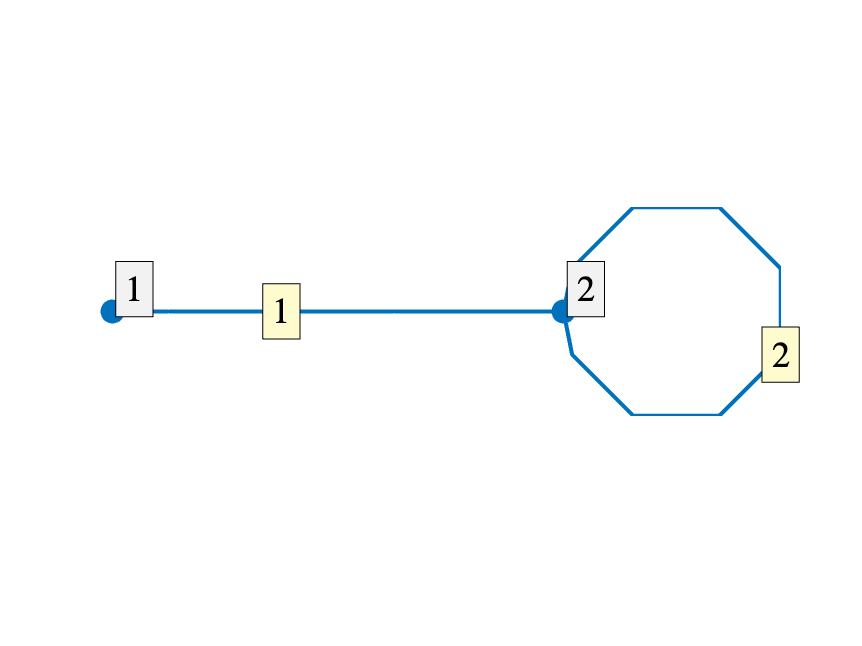

G.plot('layout')

#### (b) Spy on the matrix

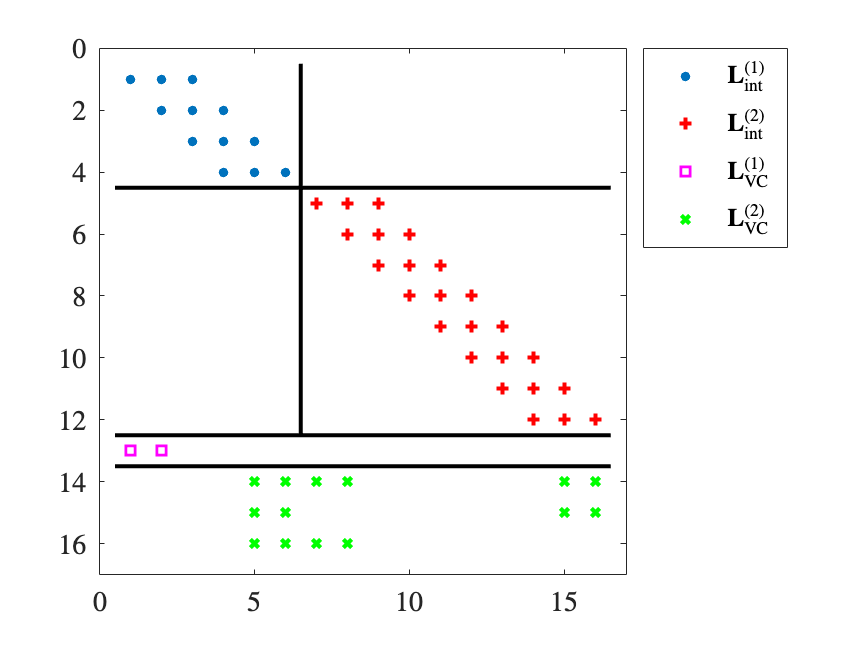

L = G.laplacianMatrixWithVC;
[Mx,My]=meshgrid(1:length(L));
spy(L.*(My<=4))
hold on
spy(L.*(4<My).*(My<13),'r+');
spy(L.*(My==13),'ms')
spy(L.*(My>13),'gx')
xlabel('')

plot([.5 16.5],4.5*[1 1],'k')
plot([.5 16.5],12.5*[1 1],'k')
plot([.5 16.5],13.5*[1 1],'k')
plot([6.5 6.5],[.5 12.5],'k')

legend('$\mathbf{L}^{(1)}_{\rm int}$',...
       '$\mathbf{L}^{(2)}_{\rm int}$',...
       '$\mathbf{L}^{(1)}_{\rm VC}$',...
       '$\mathbf{L}^{(2)}_{\rm VC}$',...
       'location','northeastoutside')

#### (c) Spy on the interpolation matrix extended with zeros

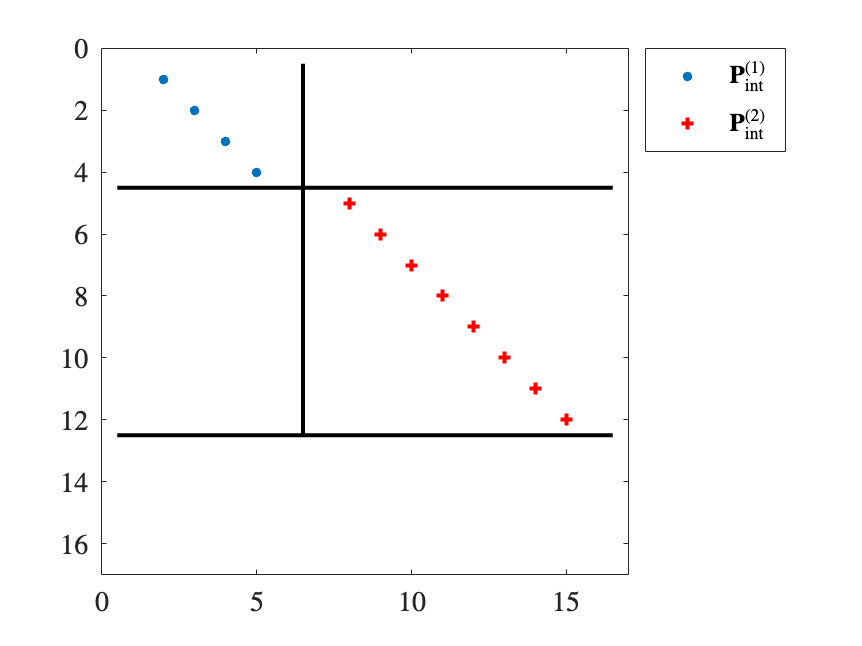


P=G.interpolationMatrixWithZeros;
[Mx,My]=meshgrid(1:16);
clf
spy(P.*(My<=4))
hold on
spy(P.*(4<My).*(My<13),'r+')
xlabel('')

plot([.5 16.5],4.5*[1 1],'k')
plot([.5 16.5],12.5*[1 1],'k')
plot([6.5 6.5],[.5 12.5],'k')

legend('$\mathbf{P}^{(1)}_{\rm int}$',...
       '$\mathbf{P}^{(2)}_{\rm int}$',...
       'location','northeastoutside')